# Figure 4 Amygdala and PAG ROI analysis

## Basic step: Select ROI-> apply mask on data-> plot activation

clear

Load Study 1 Data

load('C:\Users\KeBo\Dropbox (Dartmouth College)\2021_Ke_Bo_reappraisal_Gianaros\Data\fMRI_data\AHAB_FullData_Meta.mat')
Neg=Whole_Neg;
Neu=Whole_Neu;
Reg=Whole_Reg;

Load Study 2 Data and concatenate

load('C:\Users\KeBo\Dropbox (Dartmouth College)\2021_Ke_Bo_reappraisal_Gianaros\Data\fMRI_data\PIP_FullData_Meta.mat')
Neg=[Whole_Neg Neg];
Neu=[Whole_Neu Neu];
Reg=[Whole_Reg Reg];



Load amygdala mask

    atlas_obj = load_atlas('canlab2018_2mm');

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


Amyg = select_atlas_subset(atlas_obj, {'Amyg'});
%     parcel_means_Neg = apply_parcellation(Neg, PAG);  

    parcel_means_Neg = apply_parcellation(Neg, Amyg);  

    parcel_means_Neu = apply_parcellation(Neu, Amyg);  
    
    parcel_means_Reg = apply_parcellation(Reg, Amyg);  

    colorcoding=[110 203 99; 0 176 240;255 89 76];
colorcoding=colorcoding/255;
  LineWidth=2;
  Fontsize=20;

figure

Plot within-subject activation in CM_Amygdala


    colorcoding=[110 203 99; 0 176 240;255 89 76];
colorcoding=colorcoding/255;
G=[parcel_means_Neu(:,1) parcel_means_Neg(:,1) parcel_means_Reg(:,1)]'

G = 3×358 single matrix
    0.8393    0.2278    0.1101    0.1794    0.0059    0.2524    0.2808    0.1811   -0.0153    0.1275    1.0205    0.5428    0.2731   -0.0948    0.5459    0.3371    0.0651    0.1812    0.1967    0.2483    0.1648    0.0271   -0.2790    0.1594    0.4305    0.3580    0.0065    0.0330    0.6155    0.2960    0.0595   -0.5049    0.2001    0.1977    0.2872    0.5011    0.4663   -0.3316    0.8561    0.1019    0.0200   -0.2046    0.4080   -0.0680   -0.2095   -0.0033    0.0227    0.1150    0.2804    0.2104
    0.7966    0.1600    0.2808    0.4719   -0.0320    0.3912    0.3831    0.2964    0.1300    0.2984    1.2643    0.3922    0.0302   -0.3822    0.5745    0.4070    0.1246    0.2879    0.2757    0.2137    0.3775   -0.0589   -0.3399    0.2463    0.3896    0.2880   -0.0025   -0.0631    0.7224    0.4588    0.3558   -0.4210    0.2874    0.1506    0.5811    0.1460    0.5636   -0.2427    1.1026    0.2725    0.0708   -0.2244    0.6100    0.1199   -0.2268   -0.0527    0.1488    0

SubjectMean=mean(G,1);
Grandmean=mean(mean(G));
G_within=G-ones(3,1)*SubjectMean+Grandmean*ones(3,size(G,2));

violinplot(G_within','facecolor',colorcoding(:,:),'mc','k','bw',0.08,'plotlegend',0,'pointsize',2)

same bandwidth bw = 0.08 used for all cols


ans =   1×3 Patch array:

    Patch    Patch    Patch



set(gca,'xtick',[])
names={'Look Neutral';'Look Negative';'Regulate Negative'}

names = 3×1 cell array
    {'Look Neutral'     }
    {'Look Negative'    }
    {'Regulate Negative'}


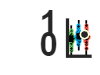

set(gca,'xtick',[1.5:3.5],'xticklabel',names)
set(gca,'xtick',[])
set(gca,'xticklabel',names)
set(gca,'linewidth',LineWidth,'Fontsize',Fontsize,'FontWeight','bold')
box off

ax = gca;
chart = ax.Children(4);
datatip(chart,2.75,0.3987);


[h p ci stat]=ttest(parcel_means_Neu(:,1), parcel_means_Neg(:,1))

h = single
1

p = single
6.4899e-21

ci = 2×1 single column vector
   -0.1260
   -0.0845


stat = struct with fields:
    tstat: -9.9986
       df: 357
       sd: 0.1992


bf1(1) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf1 = single
5.9678e+17


[h p ci stat]=ttest(parcel_means_Neg(:,1), parcel_means_Reg(:,1))

h = single
0

p = single
0.7539

ci = 2×1 single column vector
   -0.0171
    0.0236


stat = struct with fields:
    tstat: 0.3138
       df: 357
       sd: 0.1956



bf2(1) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf2 = single
0.0623


trimmean(parcel_means_Neu(:,1),98)

ans = single
0.1939

trimmean(parcel_means_Neg(:,1),98)

ans = single
0.2944

trimmean(parcel_means_Reg(:,1),98)

ans = single
0.3029

% axis([0 4 -0.3 0.8])

Plot within-subject activation in SF_Amygdala

figure
G=[parcel_means_Neu(:,2) parcel_means_Neg(:,2) parcel_means_Reg(:,2)]'

G = 3×358 single matrix
    0.7419   -0.1742    0.0534   -0.4001    0.5122    0.6921    0.2846    0.0438    0.4007    0.0671    0.5308    0.5451   -0.3011    0.1300    0.5195    0.5587    0.2486   -0.0934    0.5782    0.1656    0.5133   -0.2121   -0.0258    0.1888    0.2477    0.2414   -0.2082    0.6195    0.4647    0.2427    0.6735   -1.0047    0.4951    0.9695    0.6453    0.7707    0.2568    0.1222    0.3522   -0.0055    0.2889   -0.2498    0.1768    0.3247    0.3993   -0.4743    0.7860    0.5653    0.4516    0.1133
    0.7789   -0.0754    0.2254   -0.3469    0.2142    0.7383    0.5560   -0.0131    0.5458    0.4000    0.9478    0.6093   -0.4901   -0.5028    0.7379    0.7605    0.4208    0.0240    0.7600   -0.0244    0.5132   -0.1260   -0.2837    0.2847    0.3753    0.1708   -0.1689    0.2984    0.7684    0.2716    0.8222   -1.0511    0.3705    1.2635    0.7748    0.1622    0.5304    0.2755    0.4528   -0.0132    0.1669   -0.0730    0.1429    0.0555    0.3379   -0.6962    0.8201    0

SubjectMean=mean(G,1);
Grandmean=mean(mean(G));
G_within=G-ones(3,1)*SubjectMean+Grandmean*ones(3,size(G,2));

violinplot(G_within','facecolor',colorcoding(:,:),'mc','k','bw',0.08,'plotlegend',0,'pointsize',2)

same bandwidth bw = 0.08 used for all cols


ans =   1×3 Patch array:

    Patch    Patch    Patch



set(gca,'xtick',[])
names={'Look Neutral';'Look Negative';'Regulate Negative'}

names = 3×1 cell array
    {'Look Neutral'     }
    {'Look Negative'    }
    {'Regulate Negative'}


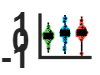

set(gca,'xtick',[1.5:3.5],'xticklabel',names)
set(gca,'xtick',[])
set(gca,'xticklabel',names)
set(gca,'linewidth',LineWidth,'Fontsize',Fontsize,'FontWeight','bold')
box off


[h p ci stat]=ttest(parcel_means_Neu(:,2), parcel_means_Neg(:,2))

h = single
1

p = single
8.4131e-23

ci = 2×1 single column vector
   -0.2255
   -0.1546


stat = struct with fields:
    tstat: -10.5417
       df: 357
       sd: 0.3410


bf1(2) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf1 = 1×2 single row vector
1.0e+19 *

    0.0597    4.3064



[h p ci stat]=ttest(parcel_means_Neg(:,2), parcel_means_Reg(:,2))

h = single
0

p = single
0.1806

ci = 2×1 single column vector
   -0.0560
    0.0106


stat = struct with fields:
    tstat: -1.3416
       df: 357
       sd: 0.3204


bf2(2) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf2 = 1×2 single row vector
    0.0623    0.1445


% axis([0 4 -0.6 1.2])

Plot within-subject activation in BL_Amygdala

figure
G=[parcel_means_Neu(:,4) parcel_means_Neg(:,4) parcel_means_Reg(:,4)]'

G = 3×358 single matrix
    0.3122   -0.0166   -0.0510    0.1217   -0.0563    0.3385    0.1470    0.0341    0.0721   -0.1002    0.7351    0.4633   -0.0273   -0.0898    0.1597    0.5510    0.0571    0.1082    0.2582   -0.2068    0.0240    0.0352   -0.0738    0.1381   -0.1070    0.1624   -0.2557    0.2366    0.1839    0.3663    0.2916   -0.2549    0.3780    0.4427    0.4628    0.3194    0.2846   -0.0597    0.1407    0.1561   -0.0051   -0.0217    0.4968    0.2800   -0.2224   -0.1783    0.2641    0.1739    0.1411    0.0644
    0.3720   -0.0095   -0.1114    0.3101   -0.1275    0.4400    0.3004    0.1769    0.0689    0.0765    0.8661    0.3595   -0.2672   -0.3989    0.2611    0.6304    0.0073    0.3304    0.1765   -0.3740    0.1211    0.0320    0.0824    0.2631   -0.0452    0.2774   -0.3180   -0.0247    0.1786    0.2554    0.4257   -0.3719    0.3815    0.2944    0.3902    0.2164    0.4879   -0.0810    0.2104    0.1433    0.0595    0.1453    0.3957    0.4751   -0.0529   -0.1255    0.1456    0

SubjectMean=mean(G,1);
Grandmean=mean(mean(G));
G_within=G-ones(3,1)*SubjectMean+Grandmean*ones(3,size(G,2));

violinplot(G_within','facecolor',colorcoding(:,:),'mc','k','bw',0.08,'plotlegend',0,'pointsize',2)

same bandwidth bw = 0.08 used for all cols


ans =   1×3 Patch array:

    Patch    Patch    Patch



set(gca,'xtick',[])
names={'Look Neutral';'Look Negative';'Regulate Negative'}

names = 3×1 cell array
    {'Look Neutral'     }
    {'Look Negative'    }
    {'Regulate Negative'}


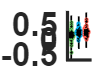

set(gca,'xtick',[1.5:3.5],'xticklabel',names)
set(gca,'xtick',[])
set(gca,'xticklabel',names)
set(gca,'linewidth',LineWidth,'Fontsize',Fontsize,'FontWeight','bold')
box off


[h p ci stat]=ttest(parcel_means_Neu(:,4), parcel_means_Neg(:,4))

h = single
1

p = single
6.6551e-18

ci = 2×1 single column vector
   -0.1003
   -0.0646


stat = struct with fields:
    tstat: -9.0963
       df: 357
       sd: 0.1715


bf1(3) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf1 = 1×3 single row vector
1.0e+19 *

    0.0597    4.3064    0.0001


[h p ci stat]=ttest(parcel_means_Neg(:,4), parcel_means_Reg(:,4))

h = single
0

p = single
0.6232

ci = 2×1 single column vector
   -0.0197
    0.0118


stat = struct with fields:
    tstat: -0.4918
       df: 357
       sd: 0.1516


bf2(3) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf2 = 1×3 single row vector
    0.0623    0.1445    0.0669


% xlim([0.5 3.5])
% ylim([-0.6 1.0])
% axis([0 4 -0.4 0.7])

Plot within-subject activation in PAG

figure
PAG = select_atlas_subset(atlas_obj, {'PAG'});
    parcel_means_Neg = apply_parcellation(Neg, PAG);  

    parcel_means_Neu = apply_parcellation(Neu, PAG);  
    
    parcel_means_Reg = apply_parcellation(Reg, PAG);  
G=[parcel_means_Neu(:,1) parcel_means_Neg(:,1) parcel_means_Reg(:,1)]'

G = 3×358 single matrix
    0.0868    0.5020    0.2072    0.3251   -0.1080    0.0651    0.2779    0.0624    0.0685    0.1792    0.0132   -0.2947   -0.0706    0.2468   -0.0302    0.5389    0.1137    0.0110   -0.0921   -0.2653    0.1466    0.4071    0.0092    0.5442   -0.0332   -0.2812   -1.0310    0.0480    0.4207    0.2329    0.1137    0.3075   -0.2950   -0.0970    1.0012    0.0210   -0.0706    0.0101   -0.1098   -0.0409   -0.4717   -0.2224    0.1493    0.0839    0.0051    0.1909    0.6032    0.1246    0.2320    0.0478
   -0.0233    0.5585    0.1635    0.3811    0.0819    0.2594    0.4661    0.0319    0.2151    0.2779    0.1286   -0.2379    0.1816    0.1614    0.0476    0.7481    0.1904    0.1269    0.3720   -0.1872    0.2719    0.5026   -0.0295    0.2231   -0.1627   -0.0256   -0.8911   -0.0741    0.6860    0.1306    0.2232    0.4150   -0.1941   -0.0295    1.1424    0.1024   -0.2009    0.3879   -0.0127    0.1733   -0.3979   -0.2262    0.4226    0.1569    0.0798    0.0809    0.9957    0

SubjectMean=mean(G,1);
Grandmean=mean(mean(G));
G_within=G-ones(3,1)*SubjectMean+Grandmean*ones(3,size(G,2));

violinplot(G_within','facecolor',colorcoding(:,:),'mc','k','bw',0.08,'plotlegend',0,'pointsize',2)

same bandwidth bw = 0.08 used for all cols


ans =   1×3 Patch array:

    Patch    Patch    Patch



set(gca,'xtick',[])
names={'Look Neutral';'Look Negative';'Regulate Negative'}

names = 3×1 cell array
    {'Look Neutral'     }
    {'Look Negative'    }
    {'Regulate Negative'}


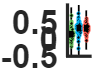

set(gca,'xtick',[1.5:3.5],'xticklabel',names)
set(gca,'xtick',[])
set(gca,'xticklabel',names)
set(gca,'linewidth',LineWidth,'Fontsize',Fontsize,'FontWeight','bold')
box off


[h p ci stat]=ttest(parcel_means_Neu(:,1), parcel_means_Neg(:,1))

h = single
1

p = single
0

ci = 2×1 single column vector
   -0.2027
   -0.1597


stat = struct with fields:
    tstat: -16.5849
       df: 357
       sd: 0.2067


bf1(4) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf1 = 1×4 single row vector
1.0e+19 *

    0.0597    4.3064    0.0001       Inf



[h p ci stat]=ttest(parcel_means_Neg(:,1), parcel_means_Reg(:,1))

h = single
0

p = single
0.7103

ci = 2×1 single column vector
   -0.0152
    0.0223


stat = struct with fields:
    tstat: 0.3717
       df: 357
       sd: 0.1805


bf2(4) = t1smpbf(stat.tstat,size(parcel_means_Neu,1),0.707)

bf2 = 1×4 single row vector
    0.0623    0.1445    0.0669    0.0635


% axis([0 4 -0.4 0.8])
